# Chapter 7 Part 1 

# Amelia Rotondo - CWID: 887925113

## Question 1:


$$\ddot{u} = \frac{v}{1+t^2}-sin(r) \\
\ddot{v} = \frac{-u}{1+t^2}+cos(r) \\
r = \sqrt{\dot{u}^2+\dot{v}^2} \\
u(0) = 1 \\
v(0) = \dot{u}(0) = \dot{v}(0) = 0


$$


#### Express this ODE in Standard Form:


$$\dot{u} = f_1(t, u, v, \dot{u}, \dot{v}) = \dot{v}, \\
\dot{v} = f_2(t, u, v, \dot{u}, \dot{v}) = \frac{v}{1 + t^2} - \frac{\sin(\sqrt{\dot{u}^2 + \dot{v}^2})}{1 + t^2}, \\
\ddot{u} = f_3(t, u, v, \dot{u}, \dot{v}) = \frac{v}{1 + t^2} - \frac{\sin(\sqrt{\dot{u}^2 + \dot{v}^2})}{1 + t^2}, \\
\ddot{v} = f_4(t, u, v, \dot{u}, \dot{v}) = -\frac{u}{1 + t^2} + \frac{\cos(\sqrt{\dot{u}^2 + \dot{v}^2})}{1 + t^2}, \\
\text{with initial conditions} \quad & u(0) = 1, \quad v(0) = 0, \quad \dot{u}(0) = 0, \quad \dot{v}(0) = 0.$$


## Question 2:


$$\begin{array}{rcl}
\dot{y} &=& ry \\
y(0) &=& 100 \\
r &=& 0.06 \\
\end{array}$$


#### Continuous Compound Interest Problem:

% Initial Data
r = 0.06; y0 = 100; 
T = 10; Tspan = [0 T]; 
hm = 1/12; hy = 1; 
y_dot = @(t, y)r.*y;
y_cont = @(t) y0.*exp(r.*t);

% Integral Evaluations
[~, e_yy] = myEuler(y_dot, Tspan, y0, hy);
[~, e_ym] = myEuler(y_dot, Tspan, y0, hm);
[~, m_ym] = myMidpoint(y_dot, Tspan, y0, hm);
[~, t_ym] = myTrapezoidal(y_dot, Tspan, y0, hm);
options = odeset('MaxStep', hm);
[~, b_ym] = ode23(y_dot, Tspan, y0, options);

% Continuous compounding
c_yy = y_cont(T);

fprintf('Eulers Method     (Yearly): %.5f\n', e_yy(end));

Eulers Method     (Yearly): 179.08477


fprintf('Eulers Method    (Monthly): %.5f\n', e_ym(end));

Eulers Method    (Monthly): 181.93967


fprintf('Midpoint Method  (Monthly): %.5f\n', m_ym(end));

Midpoint Method  (Monthly): 182.21143


fprintf('Trapezoid Method (Monthly): %.5f\n', t_ym(end));

Trapezoid Method (Monthly): 182.21143


fprintf('BS23 Method      (Monthly): %.5f\n', b_ym(end));

BS23 Method      (Monthly): 182.21188


fprintf('Continuous Compounding    : %.5f\n', c_yy);

Continuous Compounding    : 182.21188


## Question 3:

#### Part a: 

% Initial Data
Tspan = [0 1]; 
f1 = @(t, y) 1;
f2 = @(t, y) t;
f3 = @(t, y) t^2;
f4 = @(t, y) t^3;

% Solving the ODEs 
[t1, y1] = ode23(f1, Tspan, 0);
[t2, y2] = ode23(f2, Tspan, 0);
[t3, y3] = ode23(f3, Tspan, 0);
[t4, y4] = ode23(f4, Tspan, 0); 

% Compute Exact Values 
exact1 = t1;
exact2 = t2.^2 / 2; 
exact3 = t3.^3 / 3;
exact4 = t4.^4 / 4; 

% Determine Error in Reults
error1 = abs(y1 - exact1);
error2 = abs(y2 - exact2);
error3 = abs(y3 - exact3);
error4 = abs(y4 - exact4);

% Display Error Results: 
fprintf('Max Error for f(t, y) = 1   : %.4e\n', max(error1));

Max Error for f(t, y) = 1   : 1.7347e-18


fprintf('Max Error for f(t, y) = f   : %.4e\n', max(error2));

Max Error for f(t, y) = f   : 1.1102e-16


fprintf('Max Error for f(t, y) = f^2 : %.4e\n', max(error3));

Max Error for f(t, y) = f^2 : 5.5511e-17


fprintf('Max Error for f(t, y) = f^3 : %.4e\n', max(error4));

Max Error for f(t, y) = f^3 : 4.3999e-06


#### Part b:

ode23 error estimator is exact as long as you are working with a function of relatively high stiffness. Having more varied results produces a more sizable error in the estimate of ode23. 

## Question 4: 


$$erf(x)=\frac{2}{\sqrt{\pi}}\int_{0}^{x}e^{-x^{2}}dx\\
y'(x) = \frac{2}{\sqrt{\pi}}e^{-x^{2}}\\
y(0) = 0$$


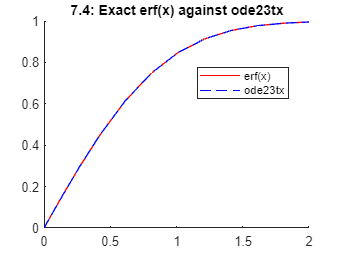

% Initial Data 
Tspan = [0 2]; y0 = 0;
f = @(x, y) 2/sqrt(pi) * exp(-x^2);
[t_tx, y_tx] = ode23tx(f, Tspan, y0);
y_exact = erf(t_tx);

% Plot Results
figure(2); clf; hold on;
plot(t_tx, y_exact, 'r', 'DisplayName', 'erf(x)');
plot(t_tx, y_tx, 'b--', 'DisplayName', 'ode23tx');
hold off; 
legend('Location', 'best');
title('7.4: Exact erf(x) against ode23tx');

## Question 5:  

#### develop myrk4.m